# EEG脑机接口-NB

## 数据导入

clear;clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')
for i = 1:54
    Pair(i) = sprintf("Channel%d & %d",Pair54(i,1),Pair54(i,2));
end

%load personal data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\Person%d\\rawTracePerson%d.mat",i,i,i);
    OSPerson = sprintf("Person%d\\Person%d\\OSPerson%d.mat",i,i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end

#### 全四人

% 定义范围
lowerBound = 4;
upperBound = 8;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=3 & Time_P%d<= 6);",no,no,no))
    eval(sprintf("thetaOS_P%d = OS_P%d(Timeindex%d,thetaindex%d,:,:);",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';
%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
%1:direct 
for j = 1:54
    freq_OS_P1 = reshape(thetaOS_P1(:,:,:,j),[],40)';
    freq_OS_P2 = reshape(thetaOS_P2(:,:,:,j),[],10)';
    freq_OS_P3 = reshape(thetaOS_P3(:,:,:,j),[],40)';
    freq_OS_P4 = reshape(thetaOS_P4(:,:,:,j),[],10)';
    freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
    % 进行交叉验证
    indices = crossvalind('Kfold', length(isMatch_all), num_folds);
    for fold = 1:num_folds
        % 划分训练集和测试集
        test_indices = (indices == fold);
        train_indices = ~test_indices;
        
        train_data = freq_OS(train_indices, :);
        train_labels = isMatch_all(train_indices);
        
        test_data = freq_OS(test_indices, :);
        test_labels = isMatch_all(test_indices);
        
        % 训练SVM模型
        nb_model = fitcnb(train_data, train_labels);
        
        % 预测测试集的标签
        predicted_labels = predict(nb_model, train_data);
        
        % 计算分类准确率
        accuracy = sum(predicted_labels == train_labels) / numel(train_labels);
        accuracies(fold) = accuracy;
    end
    
    % 计算平均准确率
    accuracy_freq_direct(j) = mean(accuracies); 
end 
figure;
bar(accuracy_freq_direct);
title("Group accuracy - NB");
ylim([0,1]);
xlabel("Pair");
ylabel("accuracy");
xticks(1:54);
xticklabels(Pair);
xtickangle(90);

#### 全四人，对theta波段的plv值取平均

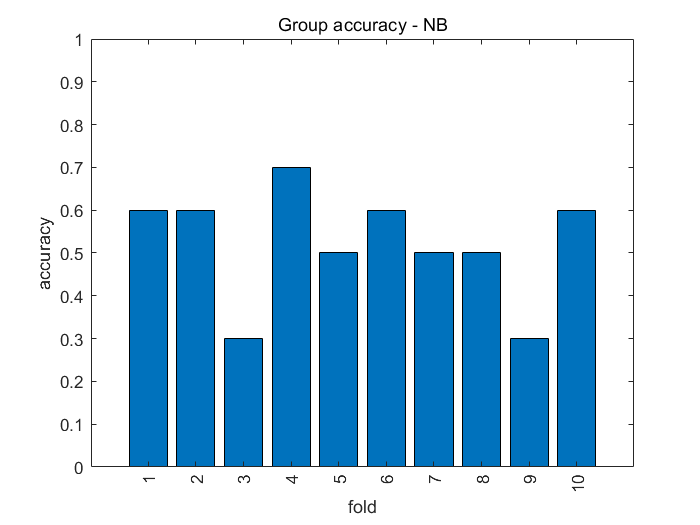

% 定义范围
lowerBound = 4;
upperBound = 8;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=0 & Time_P%d<= 7);",no,no,no))
    eval(sprintf("thetaOS_P%d = squeeze(mean(OS_P%d(Timeindex%d,thetaindex%d,:,:),2));",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';
%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
freq_OS_P1 = reshape(thetaOS_P1,[],40)';
freq_OS_P2 = reshape(thetaOS_P2,[],10)';
freq_OS_P3 = reshape(thetaOS_P3,[],40)';
freq_OS_P4 = reshape(thetaOS_P4,[],10)';
freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
% 进行交叉验证
indices = crossvalind('Kfold', length(isMatch_all), num_folds);
for fold = 1:num_folds
    % 划分训练集和测试集
    test_indices = (indices == fold);
    train_indices = ~test_indices;
    
    train_data = freq_OS(train_indices, :);
    train_labels = isMatch_all(train_indices);
    
    test_data = freq_OS(test_indices, :);
    test_labels = isMatch_all(test_indices);
    
    % 训练nb模型
    nb_model = fitcnb(train_data, train_labels);
    
    % 预测测试集的标签
    predicted_labels = predict(nb_model, test_data);
    
    % 计算分类准确率
    accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
    accuracies(fold) = accuracy;
end
accuracy_freq_direct = mean(accuracies); 
figure;
bar(accuracies);
title("Group accuracy - NB");
ylim([0,1]);
xlabel("fold");
ylabel("accuracy");
xtickangle(90);

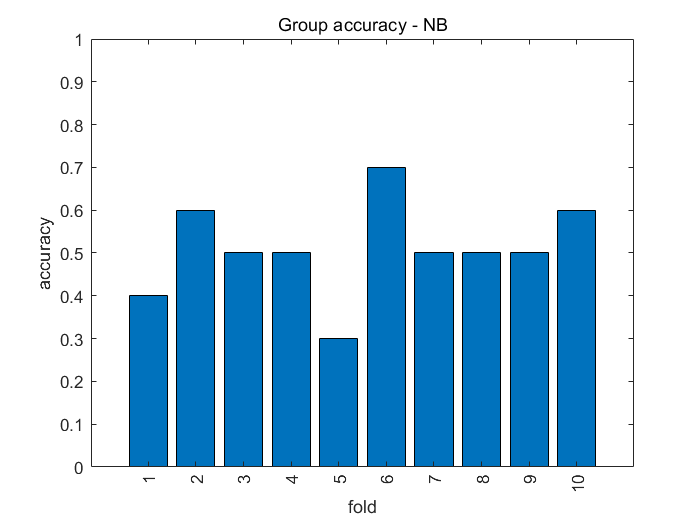

% 定义范围
lowerBound = 4;
upperBound = 8;
for no = 1:4
    % 使用逻辑索引提取满足条件的数据
    eval(sprintf("thetaindex%d = find(fOS_P%d>=lowerBound & fOS_P%d<= upperBound);",no,no,no));
    eval(sprintf("Timeindex%d = find(Time_P%d>=0 & Time_P%d<= 7);",no,no,no))
    eval(sprintf("thetaOS_P%d = OS_P%d(Timeindex%d,thetaindex%d,:,:);",no,no,no,no));
end
%将Track替换为match/nonmatch(1/0)
Track_all = [Track_P1,Track_P2,Track_P3,Track_P4];
isMatch_all = (Track_all<11)';
%10折交叉验证
% 定义交叉验证的折数
num_folds = 10;
% 初始化准确率向量
accuracies = zeros(num_folds, 1);
freq_OS_P1 = reshape(thetaOS_P1,[],40)';
freq_OS_P2 = reshape(thetaOS_P2,[],10)';
freq_OS_P3 = reshape(thetaOS_P3,[],40)';
freq_OS_P4 = reshape(thetaOS_P4,[],10)';
freq_OS = vertcat(freq_OS_P1,freq_OS_P2,freq_OS_P3,freq_OS_P4);
% 进行交叉验证
indices = crossvalind('Kfold', length(isMatch_all), num_folds);
for fold = 1:num_folds
    % 划分训练集和测试集
    test_indices = (indices == fold);
    train_indices = ~test_indices;
    
    train_data = freq_OS(train_indices, :);
    train_labels = isMatch_all(train_indices);
    
    test_data = freq_OS(test_indices, :);
    test_labels = isMatch_all(test_indices);
    
    % 训练nb模型
    nb_model = fitcnb(train_data, train_labels);
    
    % 预测测试集的标签
    predicted_labels = predict(nb_model, test_data);
    
    % 计算分类准确率
    accuracy = sum(predicted_labels == test_labels) / numel(test_labels);
    accuracies(fold) = accuracy;
end
accuracy_freq_direct = mean(accuracies); 
figure;
bar(accuracies);
title("Group accuracy - NB");
ylim([0,1]);
xlabel("fold");
ylabel("accuracy");
xtickangle(90);